syms th1(t) l_hip

x2 = l_hip*tan(th1)

$$x2(t) = l_{\mathrm{hip}}\,\tan\left({\mathrm{th}}_{1}\left(t\right)\right)$$

x2d = diff(x2,t);


## Simple Pin-Slot Model:

Basic model...

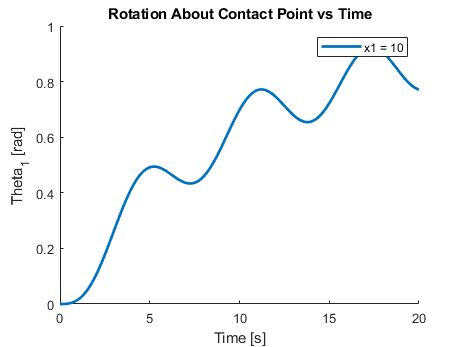

close all
clear all
clc

pinSlot.m1 = 1;
pinSlot.m2 = 1;
pinSlot.b1 = 1;
pinSlot.l_hip = 1;

pinSlot.x0 = [0; 0];

tstep = 0.1;
tend = 20;
pinSlot.t = 0:tstep:tend;
pinSlot.u = sin(pinSlot.t);

x1_range = 10;

theta1_all = zeros(length(x1_range),tend/tstep+1);
theta1d_all = zeros(length(x1_range),tend/tstep+1);
x2_all = zeros(length(x1_range),tend/tstep+1);
x2d_all = zeros(length(x1_range),tend/tstep+1);
t_all = zeros(length(x1_range),tend/tstep+1);
names = [];

for i = 1:length(t_all(:,1))

    %%Calculating moment of inertia
    pinSlot.x1 = x1_range(i); % x-position of COM1 with respect to foot coord
    pinSlot.y1 = 0; % y-position of COM1 with respect to foot coord

    pinSlot.J1 = pinSlot.m1*sqrt(pinSlot.x1^2 + pinSlot.y1^2);


    [t, oval_x] = ode45(@(t,y) pinSlotModel(t,y,pinSlot), pinSlot.t, pinSlot.x0);

    theta1_all(i,:) = oval_x(:,1);
    theta1d_all(i,:) = oval_x(:,2);
    t_all(i,:) = t;
    names = [names, "x1 = " + pinSlot.x1];

end

figure();
hold on;
plot(t_all',theta1_all','linewidth',2);
hold off;
legend(names);
xlabel('Time [s]');
ylabel('Theta_1 [rad]');
title('Rotation About Contact Point vs Time')

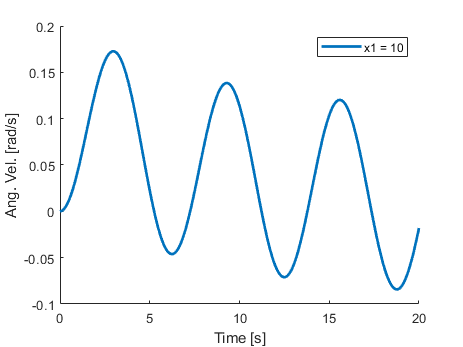


figure();
hold on;
plot(t_all',theta1d_all','linewidth',2);
hold off;
legend(names);
xlabel('Time [s]');
ylabel('Ang. Vel. [rad/s]');

Putting model into simulation...

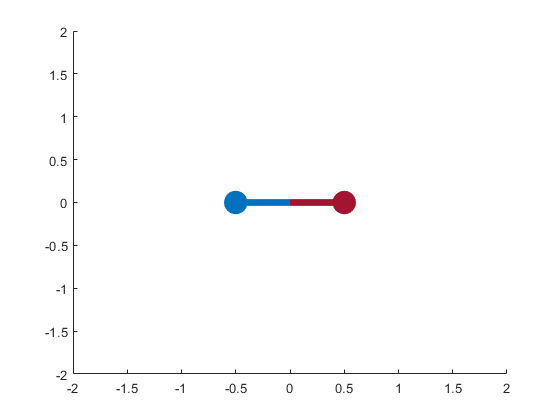

plot_tframe = 0.01;

%Left Foot
l_hip = pinSlot.l_hip;

LfootX1 = -l_hip/2;
LfootY1 = 0;
RfootX1 = l_hip/2;
RfootY1 = 0;


hfig = figure();
hax = axes();
axis([-2 2 -2 2]);
% set(gcf, 'Position',  [325, 100, 1125, 900]);
hold on;

%Initial Foot Positions
Lf_begin = [ [LfootX1, l_hip/2 + LfootX1] ; 
               [LfootY1, LfootY1]           ];
Rf_begin = [ [RfootX1 - l_hip/2, RfootX1] ;
               [RfootY1, RfootY1]           ];

%%Plotting Left Foot
Lf_contact = plot(Lf_begin(1,1), Lf_begin(2,1),'.','markerSize',60, 'color', [0 0.4470 0.7410]);
Lf_midline = plot(Lf_begin(1,:), Lf_begin(2,:), 'linewidth',5, 'color', [0 0.4470 0.7410]);


%%Plotting Right Foot
Rf_contact = plot(Rf_begin(1,end), Rf_begin(2,end),'.','markerSize',60, 'color', [0.6350 0.0780 0.1840]);
Rf_midline = plot(Rf_begin(1,:), Rf_begin(2,:), 'linewidth',5, 'color', [0.6350 0.0780 0.1840]);

hold off;

%     if SYS.writeVideo
%         vid = VideoWriter(SYS.vidFilename);
%         vid.FrameRate = 60;
%         vid.Quality = 98;
%         open(vid);
%     end


for i = 1:length(pinSlot.t)
    tic

    LfootX1 = -l_hip/2;
    LfootY1 = 0;
    RfootX1 = l_hip/2;
    RfootY1 = theta1_all(1,i);

    Lf_new = Lf_begin;
    Rf_new = [ [RfootX1 - l_hip/2, RfootX1] ;
               [RfootY1, RfootY1]           ];

    %%Updating Foot Positions
    Lf_new = rotateFoot(Lf_new, -theta1_all(1,i), LfootX1, LfootY1);
    Rf_new = rotateFoot(Rf_new, -theta1_all(1,i), LfootX1, LfootY1);


    %Left Foot
    Lf_contact.XData = Lf_new(1,1);
    Lf_contact.YData = Lf_new(2,1);
    
    Lf_midline.XData = Lf_new(1,:);
    Lf_midline.YData = Lf_new(2,:);
    

    %Right Foot
    Rf_contact.XData = Rf_new(1,end);
    Rf_contact.YData = Rf_new(2,end);
    
    Rf_midline.XData = Rf_new(1,:);
    Rf_midline.YData = Rf_new(2,:);


    x = toc;
    if (x < plot_tframe)
        pause(plot_tframe - x);
        %             if SYS.writeVideo
        %                 frame = getframe(gcf);
        %                 writeVideo(vid,frame);
        %             end
    end

end


%     if SYS.writeVideo
%         close(vid);
%     end



## Functions:

function dxdt = pinSlotModel(t,y,SYS)

A = [ 0         1       ;
      0  -SYS.b1/SYS.J1 ];
B = [0; SYS.m2*SYS.l_hip/SYS.J1];

x = [y(1); y(2)];
u = sin(t);

dxdt = A*x + B*u;

end

function rotated_foot = rotateFoot(foot, theta, c1, c2)

temp = foot(1,:) + foot(2,:)*1j;

temp = temp - (c1 + c2*1j);
temp = temp.*(1/sqrt(1+(tan(theta)^2))*(1+tan(theta)*1j));
temp = temp + (c1 + c2*1j);


rotated_foot = [real(temp); imag(temp)];

end